# Deutsch-Jozsa Algorithm

this example shows an application of the quantum Deutsch-Jozsa algorithm [1] in order to achive an exponential speedup compared to a classical solution. First we will explain the Deutsch-Jozsa problem, then we are gonna propose a classical solution, and lastly a quantum solution using the Deutsch-Jozsa algorithm.

## The Deutsch-Jozsa Problem

the Deutsch-Jozsa problem is a decision problem that determines if a given boolean function

 
$$f:{\left\lbrace 0,1\right\rbrace }^n \to \left\lbrace 0,1\right\rbrace$$


is constant (it always return the same value) or balanced (it returns 0 for half of the inputs and 1 for the other half of the inputs).

As we will se in the next sections a classica algorithms requires $2^{n-1} +1$queries while the Deutsch-Jozsa quantum algorithm only needs one query to it's oracle, providing an exponential speedup.

## Classical Solution

let's assume we have a 4 bit input

n = 4; % number of bits of the input, 2^3 = 8 possible inputs

and let's create a constant function and a balanced function

f_constant = @(x) 1;
f_balanced = @(x) mod(sum(x - '0'), 2); % bitwise XOR

num_inputs = 0:1:15;
inputs = dec2bin(num_inputs); % converting all the possible inputs in binary

% computing both functions for each input
outputs_constant = arrayfun(@(i) f_constant(inputs(i, :)), 1:length(num_inputs));
outputs_balanced = arrayfun(@(i) f_balanced(inputs(i, :)), 1:length(num_inputs));

from the functions truth tables it's clear one is constant and the other one is balanced

T = table(inputs, outputs_constant', outputs_balanced', 'VariableNames', {'Input', 'f_constant', 'f_balanced'});

disp(T);

    Input    f_constant    f_balanced
    _____    __________    __________

    0000         1             0     
    0001         1             1     
    0010         1             1     
    0011         1             0     
    0100         1             1     
    0101         1             0     
    0110         1             0     
    0111         1             1     
    1000         1             1     
    1001         1             0     
    1010         1             0     
    1011         1             1     
    1100         1             0     
    1101         1             1     
    1110         1             1     
    1111         1             0     



using a classical approch, the best way to determinate if $f$ is constant or balanced is to check the output of $f\left(x\right)\;$ for more than half of the possible values. If all the outpus are the same $f$ is constant, if not $f$ is balanced.

in our case, with sixteen possible inputs this means we need to compute $f$ nine times, but in a more generic context, considering n-digits inputs ($2^n$ possible combinations), we would need $2^{n-1} +1$queries, making the worst case complexity of this methode $O\left(2^n \right)$

let's demonstrate it in our four digits input scenario

evaluations_constant = 0;
evaluations_balanced = 0;

isConstant1 = true;

first_value = f_constant(inputs(1, :));
evaluations_constant = evaluations_constant + 1;
disp("evaluation number 1 -> value = " + first_value);

evaluation number 1 -> value = 1


for i=2:length(num_inputs)/2 + 1
    disp("evaluation number " + i + " -> value = " + f_constant(inputs(i, : )));
    if(f_constant(inputs(i, : )) ~= first_value)
        isConstant1 = false;
        disp("this value differs from the previous, teh function is constant!")
        break;
    end
    evaluations_constant = evaluations_constant + 1;
end

evaluation number 2 -> value = 1
evaluation number 3 -> value = 1
evaluation number 4 -> value = 1
evaluation number 5 -> value = 1
evaluation number 6 -> value = 1
evaluation number 7 -> value = 1
evaluation number 8 -> value = 1
evaluation number 9 -> value = 1


if isConstant1
    disp(['Classical Result: The first function is CONSTANT. Evaluations: ', num2str(evaluations_constant)]);
else
    disp(['Classical Result: The  first function is BALANCED. Evaluations: ', num2str(evaluations_constant)]);
end

Classical Result: The first function is CONSTANT. Evaluations: 9


isConstant2 = true;

first_value = f_balanced(inputs(1, :));
evaluations_balanced = evaluations_balanced + 1;
disp("evaluation number 1 -> value = " + first_value);

evaluation number 1 -> value = 0


for i=2:length(num_inputs)/2 +1
    disp("evaluation number " + i + " -> value = " + f_balanced(inputs(i, :)));
    if(f_balanced(inputs(i, :)) ~= first_value)
        isConstant2 = false;
        disp("this value differs from the previous, teh function is constant!")
        break;
    end
    evaluations_balanced = evaluations_balanced + 1;
end

evaluation number 2 -> value = 1


this value differs from the previous, teh function is constant!


if isConstant2
    disp(['Classical Result: The second function is CONSTANT. Evaluations: ', num2str(evaluations_balanced)]);
else
    disp(['Classical Result: The second function is BALANCED. Evaluations: ', num2str(evaluations_balanced)]);
end

Classical Result: The second function is BALANCED. Evaluations: 1


in this case we need nine iterations to assert the first function is constant (as expected) and just one iteration to assert that the second function is balanced, this is because in this case

 
$$f_{\textrm{balanced}} \left(000\right)=0\;\;\not= {\;f}_{\textrm{balanced}} \left(001\right)=1$$


making it immediatly obvious that the function is not constant.

## Solving Using Deutsch-Jozsa Quantum Algorithm

#### Inizialization

the quantum circuit must have a register with n qubits to rappresent the input values $x$ and a single qubit register to store the result $f\left(x\right)$, this means our input state is


$$|\psi_o \rangle =|0\rangle^{\otimes n} \;|1\rangle$$


#### Explaining the Circuit

after applying an Hadamard transorm to both the input register and the result register the state becomes


$$|\psi_1 \rangle =\sum_{x\in {\left\lbrace 0,1\right\rbrace }^n }^{2^n -1} \frac{|x\rangle }{\sqrt{2^n }}\;\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$$


the input register is now a superposition of all values and the result register is in a superposition of 0 and 1. next the function $f$ is evaluated by the oracle $U_f :|x,y\rangle \to |x,y\oplus f\left(x\right)\rangle$ giving


$$|\psi_2 \rangle =\sum_x^{2^n -1} \frac{{\left(-1\right)}^{f\left(x\right)} |x\rangle }{\sqrt{2^n }}\;\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$$


it is clear from this formula that now the information about $f\left(x\right)\;$is stored in the amplitude. Finally after applying another Hadamard transform on the input register we get the form


$$|\psi_3 \rangle =\sum_z^{2^n -1} \sum_x^{2^n -1} \frac{{\left(-1\right)}^{x\cdot z+f\left(x\right)} |z\rangle }{2^n }$$

$$\left(\frac{|0\rangle -|1\rangle }{\sqrt{2}}\right)$$


Note that the amplitude for the state $|0\rangle^{\otimes n} \;$is $\sum_x \frac{{\left(-1\right)}^{f\left(x\right)} }{2^n }$ so in the case where $f$ is constant the amplitude for  $|0\rangle^{\otimes n} \;$is +1 or -1, depending on the constant value $f\left(x\right)$ takes. Because $|\psi_3 \rangle$ is of unit length it follows that all the other amplitudes must be zero and an observervation must yield 0s for all qubits in the input register. If $f$ is balanced than the positive and negative contributions to the amplitudes for $|0\rangle^{\otimes n} \;$cancel, leaving an amplitude of zero, and a mesurement must yield a result other than 0 on al least one qubit in the input register.

you can see in this picture [2] the circuit in its whole

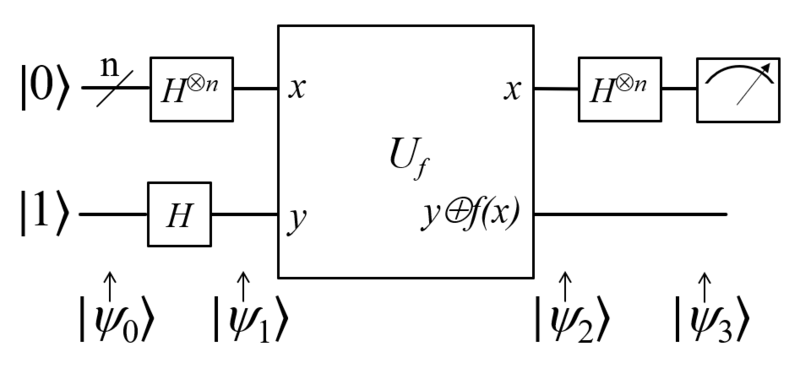

#### Function Specific Implementation

lets's implement a circuit with an oracle specific for our balanced and constant functions and see the results:

function qc = DJcircuit(numQubits, f_constant)
    totalQubits = numQubits + 1;

    gates = [];

    % apply Hadamard gate on each qubit
    for n = 1:totalQubits
        gates = [gates, hGate(n)];
    end

    % create oracle
    if f_constant  
        gates = [xGate(totalQubits), gates];
    else
        for n = 1:numQubits
            gates = [gates, cxGate(n, totalQubits)];
        end
    end

    % apply Hadamard on the input register
    for n = 1:numQubits
        gates = [gates, hGate(n)];
    end
    
    qc = quantumCircuit(gates, numQubits + 1); 
end

now just choose the bit length of the input domain and the function type and see the results yourself

numQubits = 6;
f_constant = false; % set true to build the circuit of the contant function and false to build the circuit of the balanced function 
%% IMPORTANT!!! this parameter has no role in the computation of the output, it's just a flag to decide which oracle to implement
qc = DJcircuit(numQubits, f_constant);


now let's plot the circuit

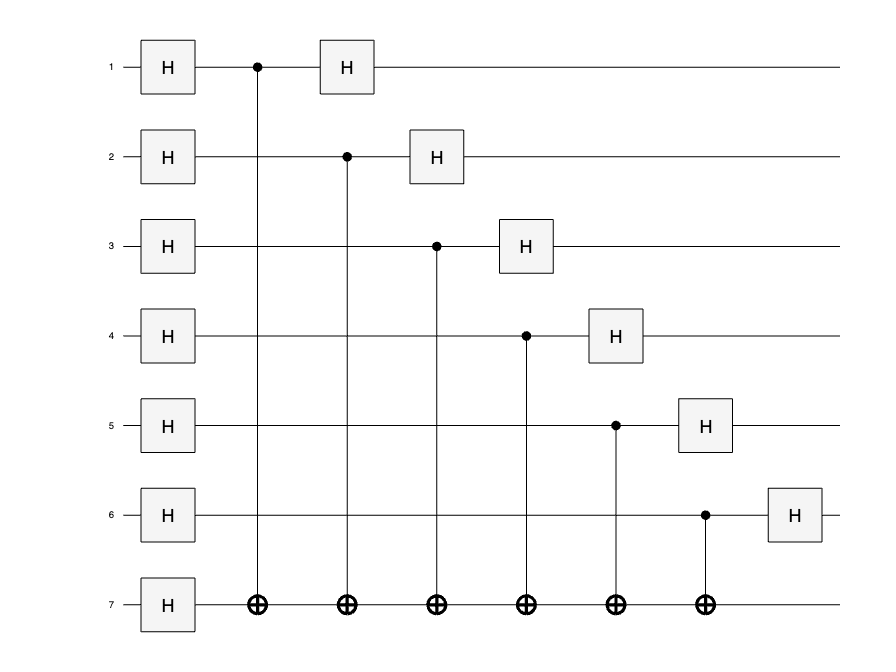

plot(qc);

finally, let's simulate the circuit and see the results

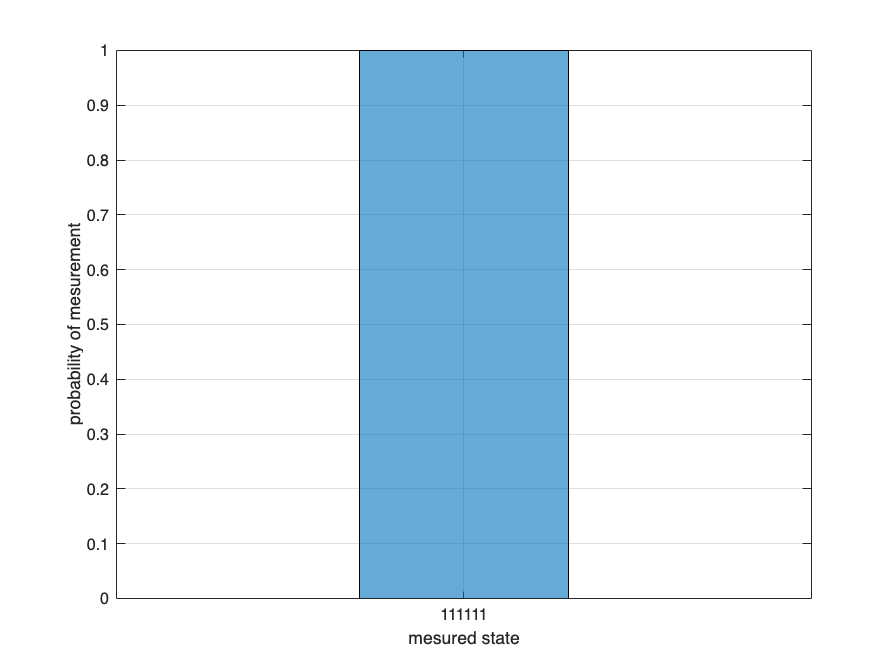

inputString = ['0' * ones(1, numQubits), '1'];
s = simulate(qc, inputString);

figure;
histogram(s, 1:numQubits);
xlabel('mesured state');
ylabel('probability of mesurement');
grid on;

As expected a balanced function yields a mesurement different from all 0s with probability 1 and a constant fuction yields a mesurement of all 0s with probability 1.

We notice that, as mentioned before, we obtain this result with only one query to the oracle, meaning we obtained an exponential speedup compared to a classical solution.

## Referneces

[1] D Deutsch & R Jozsa, “Rapid solution of problems by quantum computation”

[2] Michael A. Nielsen, Isaac L. Chuang "Quantum Computation and Quantum Information"